# Create and Customize Horizontal Bar Graphs

Horizontal bar graphs present data using rectangular bars with widths proportional to the values that they represent.

### Read Temperature Data

We will use `'BostonTemp.mat' `to demonstrate how to create and customize horizontal bar graphs. The MAT-file contains monthly temperature data of Boston, MA (Logan Airport) by the U.S. National Oceanic and Atmospheric Administration between 2000 and 2020. 

load BostonTemp.mat

### Basic Horizontal Bar Graph

Visualize the monthly temperature for one of the years between 2000 and 2020.

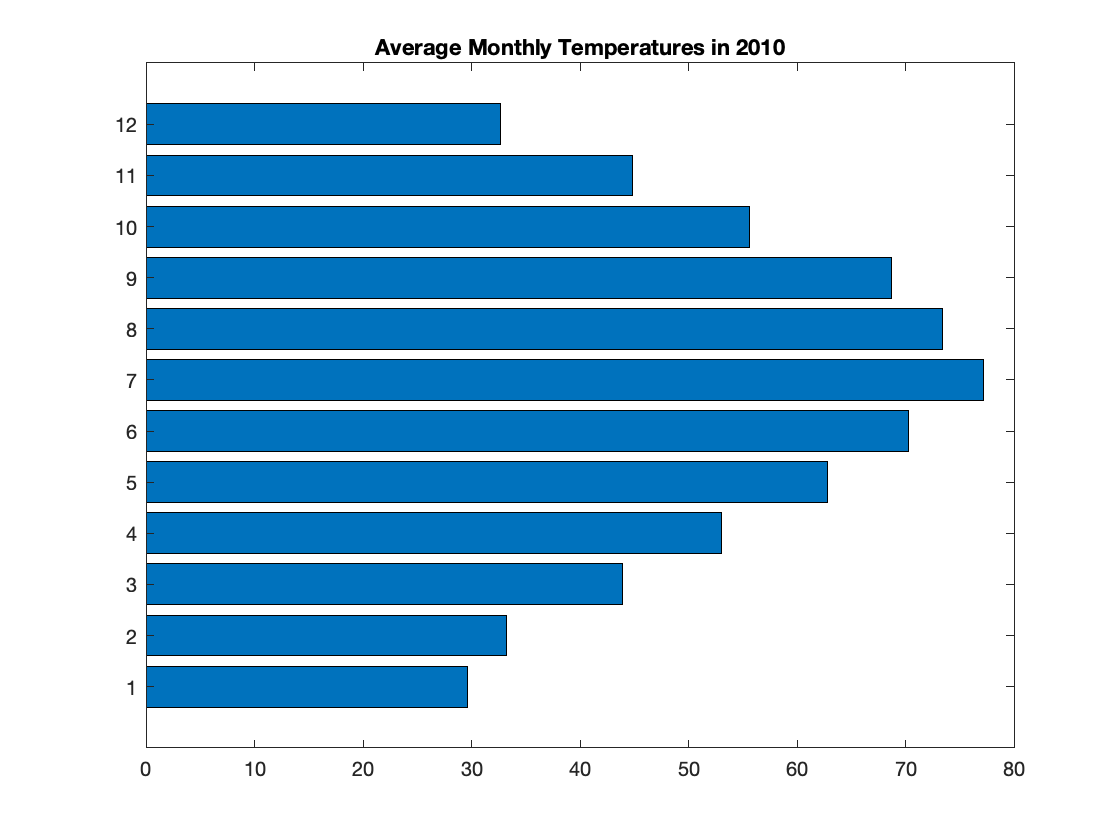

yearIdx = 11;      % choose a year
barh(1:12,Temperatures(yearIdx,:));
title(sprintf("Average Monthly Temperatures in %d",Year(yearIdx)))

## Customization

### Customize Bar Appearance and Add Custom Axis Ticks

A bar graph can be customized to have user-specified bar width, color and transparency. Use the third argument to `barh` to modify the bar width. Modify the *FaceColor* and *FaceAlpha *properties using Name, Value pairs.

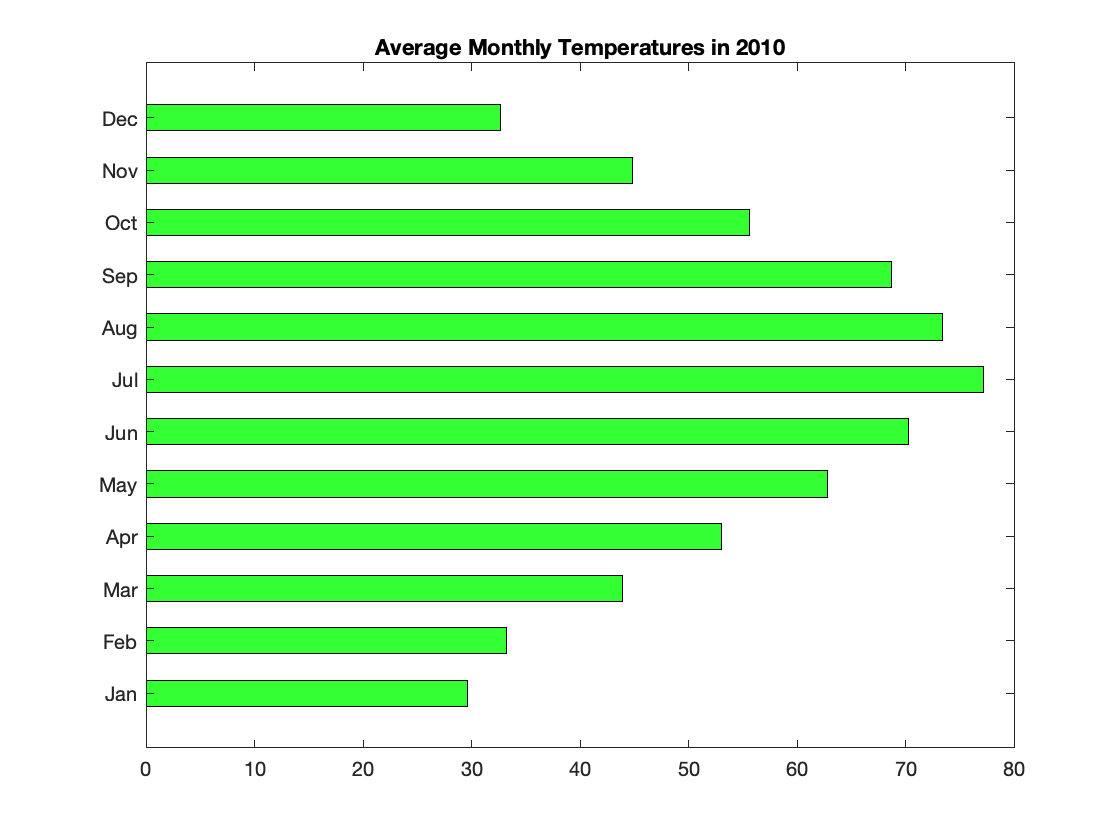

barWidth = 0.5;
barColor = "green";
barTransparency = 0.8;           % Specify any number between 0.1 and 1.0

b = barh(1:12,Temperatures(yearIdx,:),barWidth,...      % Specify bar width in the third argument
    "FaceColor",barColor, ...                           % Specify bar color
    "FaceAlpha",barTransparency);                       % Specify bar transparency

yticklabels(Months)
title(sprintf("Average Monthly Temperatures in %d",Year(yearIdx)))

### Group Bar Graphs and Customize Individual Bar Colors

Grouped bar graphs can be used to compare measured values for different discrete categories or cases using two or more color-coded bars for each category or case. Specify a legend and axes labels to complete the graph.

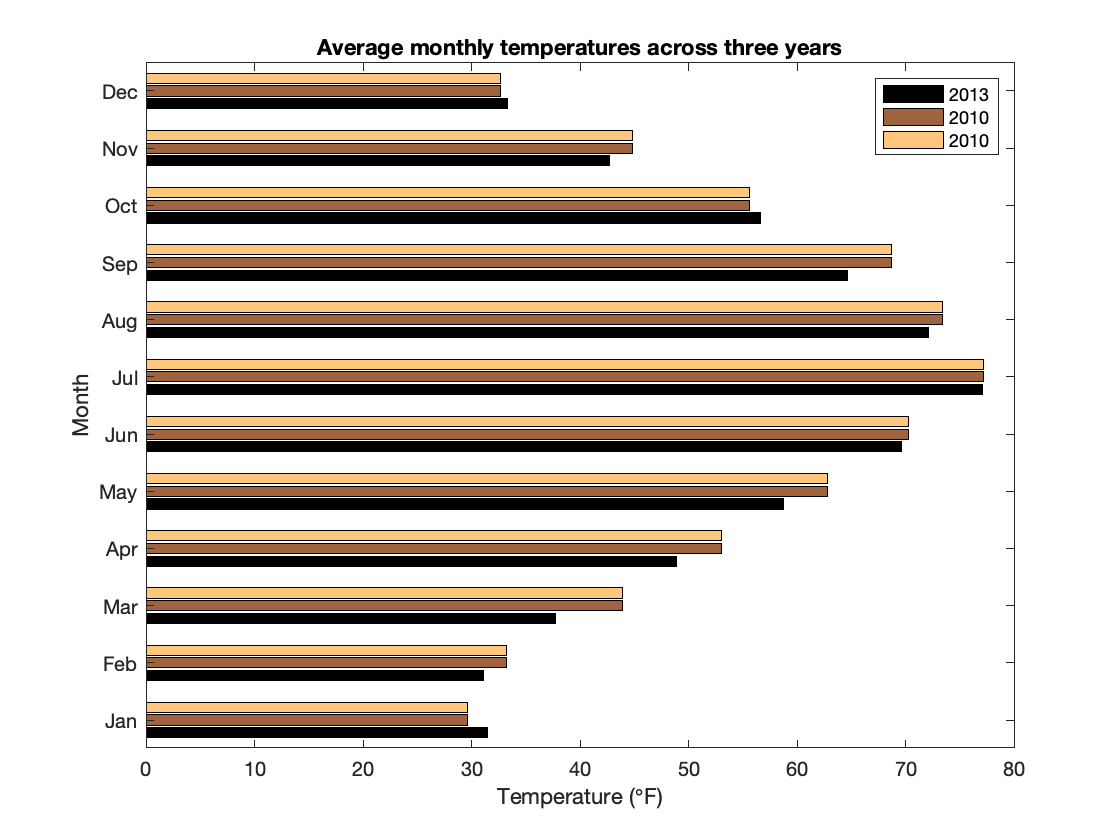

yearIdx1 = 14;
yearIdx2 = 11;
yearIdx3 = 11;
TempGroup = [Temperatures(yearIdx1,:);Temperatures(yearIdx2,:);...
    Temperatures(yearIdx3,:)];

figure
b1 = barh(1:12,TempGroup,...
    "FaceColor","flat");                % Set FaceColor to flat to use Colormaps
colormap copper           % Choose a colormap
for k = 1:3
    b1(k).CData = k;                    % Chooses the colors from the colormap specified
end

legend(sprintf("%d",Year(yearIdx1)),sprintf("%d",Year(yearIdx2)),sprintf("%d",Year(yearIdx3)))
title("Average monthly temperatures across three years");
yticklabels(Months)
ylabel("Month")
xlabel("Temperature (\circF)")

## **Additional Information**

### **Get All Bar Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Bar, uncomment the following code. View or modify these properties using dot notation.

% get(b)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[Horizontal Bar Graph](https://www.mathworks.com/help/matlab/ref/barh.html)

Copyright (c) 2021, The MathWorks, Inc.